tv1=2*[1/2.1 1/2.06 1/2.11 1/2.04]; s_tv1=sqrt(var(tv1)); m_tv1=mean(tv1);
tv2=3*[1/1.29 1/1.42 1/1.35 1/1.29]; s_tv2=sqrt(var(tv2)); m_tv2=mean(tv2);
tv3=-2*[1/2.18 1/2.28 1/2.28 1/2.3]; s_tv3=sqrt(var(tv3)); m_tv3=mean(tv3);

mv1=[0.97 0.98 1 0.97 0.91 0.94 0.95 0.97 0.87 0.94 0.95 0.96 0.87 0.95 0.95 0.97];
s_mv1=sqrt(var(mv1)); m_mv1=mean(mv1);

mv2=[2.29 2.29 2.28 2.26 2.32 2.31 2.31 2.29 2.28 2.29 2.3 2.29];
s_mv2=sqrt(var(mv2)); m_mv2=mean(mv2);

mv3=-1*[0.87 0.87 0.87 0.88 0.81 0.85 0.85 0.75 0.87 0.88 0.89 0.89 0.88 0.88 0.89 0.88];
s_mv3=sqrt(var(mv3)); m_mv3=mean(mv3);

m1=0.95; s1=0.022;
m2=2.29; s2=0.005;
m3=-0.86; s3=0.029;

x=-3:0.001:4;

p1=normpdf(x,m_mv1,s_mv1);
p2=normpdf(x,m_mv2,s_mv2);
p3=normpdf(x,m_mv3,s_mv3);

pv1=normpdf(x,m_tv1,s_tv1);
pv2=normpdf(x,m_tv2,s_tv2);
pv3=normpdf(x,m_tv3,s_tv3);

fig = figure;
fig.PaperPositionMode = 'auto';
fig.PaperUnits = 'normalized';

subplot(3,1,1);
hold on;
plot(x,p1,'Color','#94C08C','LineWidth',4);
xline(m_mv1,':','Color','k','LineWidth',6);
xline(m_tv1,':','Color','k','LineWidth',6)
plot(x,pv1,'--','Color','#94C08C','LineWidth',4);
xlabel("m/s");
xlim([m_mv1-4*s_mv1,m_mv1+4*s_mv1]); xticks(-3:0.01:4);
legend("Målte hastigheter (V_{11-14})","","", "Teoretisk hastighet (V_1)",'Fontsize',25, 'Location', 'west');
grid;
ax = gca

ax =   Axes with properties:

             XLim: [0.8025 1.0913]
             YLim: [0 30]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.7093 0.7750 0.2157]
            Units: 'normalized'

  Show all properties


ax.LineWidth = 1;
ax.FontSize=20;
ax.FontWeight='bold';

subplot(3,1,2);
hold on;
plot(x,p2,'Color','#ECD28B','LineWidth',4);
xline(m_tv2,':','Color','k','LineWidth',6);
xline(m_mv2,':','Color','k','LineWidth',6)
plot(x,pv2,'--','Color','#ECD28B','LineWidth',4);
xlabel("m/s");
xlim([m_mv2-4*s_mv1,m_mv2+4*s_mv1]); xticks(-3:0.01:4);
ylim([0 25]);
legend("Målte hastigheter (V_{21-24})","","", "Teoretisk hastighet (V_{2})",'Fontsize',25, 'Location', 'west');
grid;
ax = gca

ax =   Axes with properties:

             XLim: [2.1481 2.4369]
             YLim: [0 25]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.4096 0.7750 0.2157]
            Units: 'normalized'

  Show all properties


ax.LineWidth = 1;
ax.FontSize=20;
ax.FontWeight='bold';

subplot(3,1,3);
hold on;
plot(x,p3,'Color','#EBADB8','LineWidth',4);
xline(m_mv3,':','Color','k','LineWidth',6);
xline(m_tv3,':','Color','k','LineWidth',6)
plot(x,pv3,'--','Color','#EBADB8','LineWidth',4);
xlabel("m/s");
xlim([m_mv3-4*s_mv1,m_mv3+4*s_mv1]); xticks(-3:0.01:4);
legend("Målte hastigheter (V_{31-34})","","", "Teoretisk hastighet (V_{3})",'Fontsize',25, 'Location', 'west');
grid;
ax = gca

ax =   Axes with properties:

             XLim: [-1.0075 -0.7187]
             YLim: [0 20]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.2157]
            Units: 'normalized'

  Show all properties


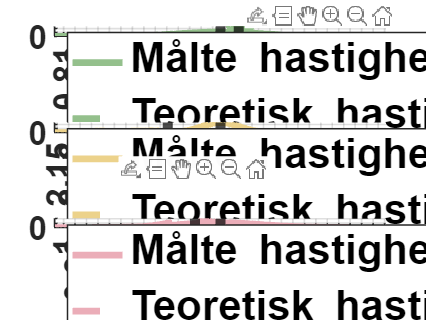

ax.LineWidth = 1;
ax.FontSize=20;
ax.FontWeight='bold';